% parameters
L0_ss = param(1); % [m]
k0_ss = param(2); % nominal leg stiffness [N/m]
m_M = param(3); % hip mass [kg]
m_swLeg = param(4); % [kg]
m_swFoot = param(5); % [kg]
I_swLeg = param(6); %
I_swFoot = param(7); %
L_thigh = param(8); % [m]
k_swFoot = param(9); %
k_swLeg = param(10); %
theta0 = param(11); %[rad]
r0 = param(12); % [m]
gravi = param(13); % gravitational acc

L0_ds = param(14); % [m] free length of the springs in the DS
k0_ds = param(15); % [N/m] stiffness of the springs in the DS

% flags
f_SS = flag(end,1); % indicates which stance phase it is
foot = flag(end,2); % location of the stance foot
foot_prev = flag(end,3); % previous location of the stance foot

% y_swFoot and dy_swFoot

x_M = simout(:,1);
y_M = simout(:,2);
theta = simout(:,3);
r = simout(:,4);

dx_M = simout(:,7);
dy_M = simout(:,8);
dtheta = simout(:,9);
dr = simout(:,10);

y_swFoot = y_M + (r+L_thigh).*sin(theta);
dy_swFoot = dy_M + dr.*sin(theta) + (r+L_thigh).*cos(theta).*dtheta;

dummy = [y_swFoot, dy_swFoot];

y_swFoot_ref = dc.simout_ss(:,2) + (L_thigh + dc.simout_ss(:,4)).*sin(dc.simout_ss(:,3));
y_swFoot_star = ref_star.ss.y_swFoot_star

y_swFoot_star =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


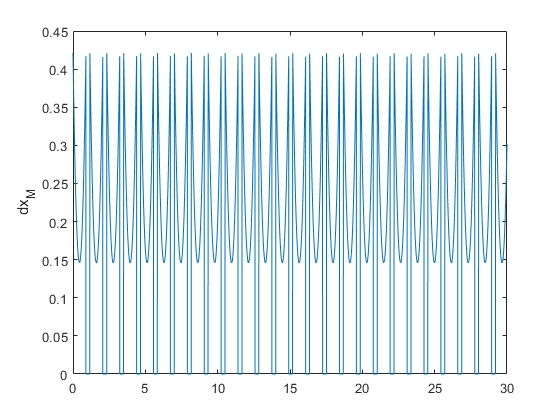


% figure()
% plot(time, y_swFoot)
% hold on
% plot(dc.time_ss, y_swFoot_ref)
% plot()
% xlim([0,1.2])
% grid on
% ylabel('y_{swFoot} [m/s]')

figure()
plot(time, dx_M)
hold on
% plot(time, )
ylabel('dx_M')

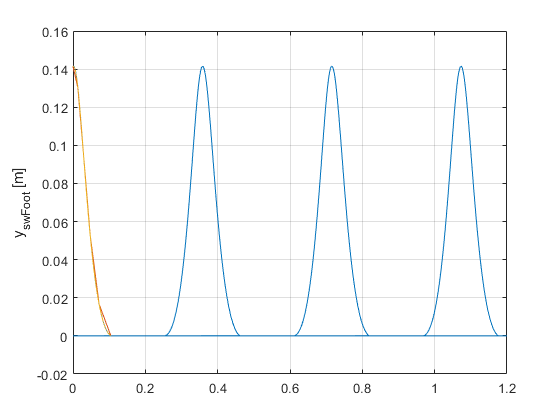


figure()
plot(x_M, y_swFoot)
hold on
plot(dc.simout_ss(:,1), y_swFoot_ref)
plot(ref_star.ss.x_M_star, y_swFoot_star)
xlim([0,1.2])
grid on
ylabel('y_{swFoot} [m]')

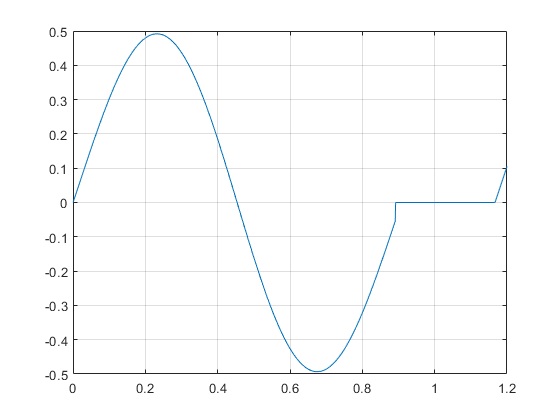


figure
plot(time, dy_swFoot)
xlim([0, 1.2])
grid on

## Inputs

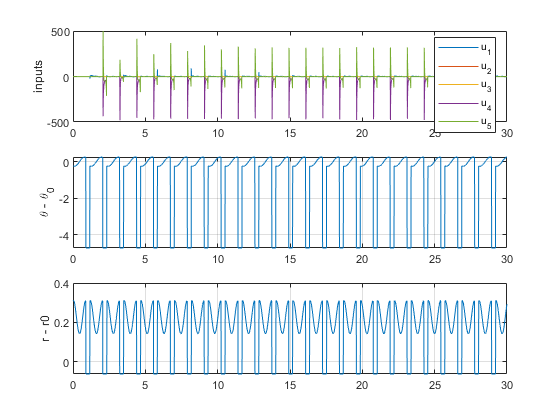

figure

x_lim = time(end);

subplot(3,1,1)
plot(time(2:end), inputs(2:end, :))
hold on
% plot(time, flag(:,1)*10000)
xlim([0, x_lim])
ylabel('inputs')
legend('u_1','u_2','u_3','u_4','u_5')

subplot(3,1,2)
plot(time, simout(:,3) - theta_s0)
grid on
xlim([0, x_lim])
ylabel('\theta - \theta_0')

subplot(3,1,3)
plot(time, simout(:,4) - r_s0)
grid on
xlim([0, x_lim])
ylabel('r - r0')

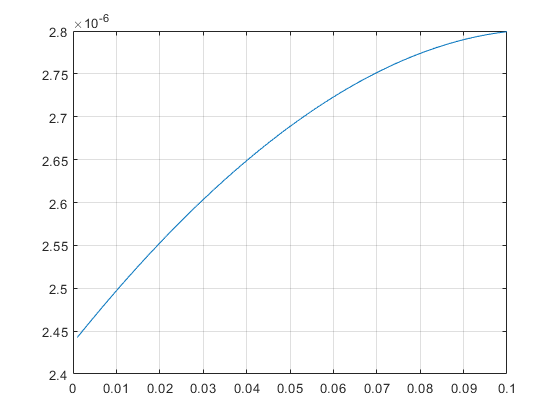




figure()
plot(time(2:end), det_A_ss(2:end))
xlim([0, 0.1])
grid on

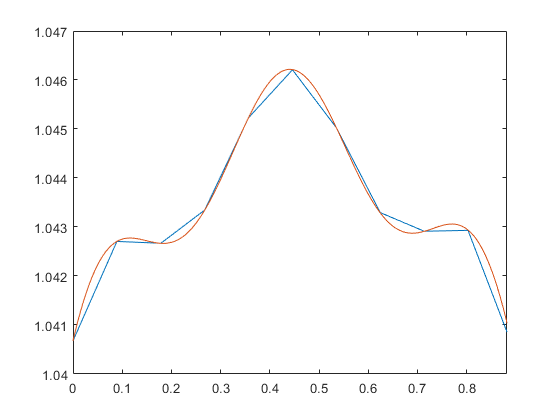

% ss tracking
figure()
plot([dc.time_ss], dc.simout_ss(:,2))
hold on
plot(time, y_M)
xlim([0,dc.time_ss(end)-0.01])

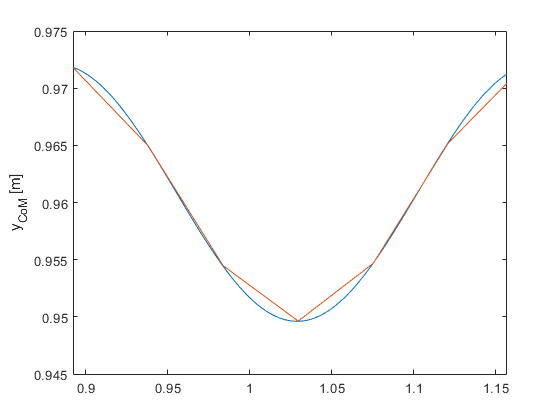

% ds tracking

x_CoM = simout(:,5);
y_CoM = simout(:,6);

dx_CoM = simout(:,11);
dy_CoM = simout(:,12);

figure()
plot(time, y_CoM)
hold on
plot(dc.time_ss(end) + dc.time_ds, dc.simout_ds(:,2))

xlim([dc.time_ss(end), dc.time_ds(end) + dc.time_ss(end) - 0.01])
    ylabel('y_{CoM} [m]')

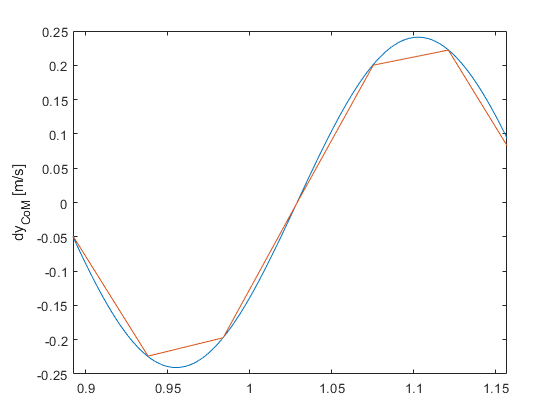



figure()
plot(time, dy_CoM)
hold on
plot(dc.time_ss(end) + dc.time_ds, dc.simout_ds(:,4))

xlim([dc.time_ss(end), dc.time_ds(end) + dc.time_ss(end) - 0.01])
ylabel('dy_{CoM} [m/s]')

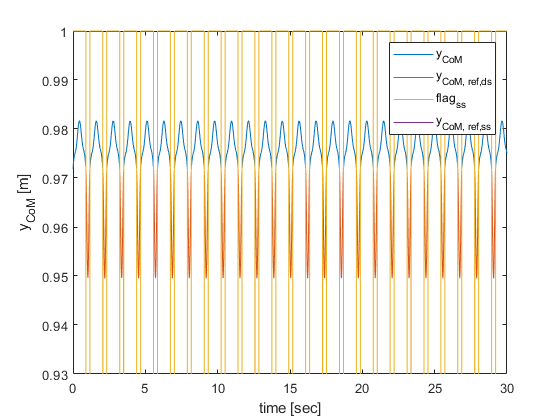

% calculating DC com in ss
y_swLeg = dc.simout_ss(:,2) + L_thigh*sin(dc.simout_ss(:,3))/2;
y_swFoot = dc.simout_ss(:,2) + (L_thigh + dc.simout_ss(:,4)).*sin(dc.simout_ss(:,3));

dy_swLeg = dc.simout_ss(:,6) + L_thigh*cos(dc.simout_ss(:,3)).*dc.simout_ss(:,7)/2;
dy_swFoot = dc.simout_ss(:,6) + (dc.simout_ss(:,8)).*sin(dc.simout_ss(:,3)) ...
    + (L_thigh + dc.simout_ss(:,4)).*cos(dc.simout_ss(:,3)).*dc.simout_ss(:,7);

y_dcCoM_ss = (m_M.*dc.simout_ss(:,2) + m_swLeg.*y_swLeg + m_swFoot.*y_swFoot)./(m_M + m_swFoot + m_swLeg);
dy_dcCoM_ss = (m_M.*dc.simout_ss(:,6) + m_swLeg.*dy_swLeg + m_swFoot.*dy_swFoot)./(m_M + m_swFoot + m_swLeg);

% calculating the com of simout
for k = 1:length(time)
    if flag(k,1) == 1
        x_swLeg_calc(k) = x_M(k) + L_thigh*cos(theta(k))/2;
        x_swFoot_calc(k) = x_M(k) + (L_thigh + r(k))*cos(theta(k)) - flag(k,2);
        
        y_swLeg_calc(k) = y_M(k) + L_thigh*sin(theta(k))/2;
        y_swFoot_calc(k) = y_M(k) + (L_thigh + r(k))*sin(theta(k));
        
        x_CoM_calc(k) = (x_M(k)*m_M + x_swLeg_calc(k)*m_swLeg + x_swFoot_calc(k)*m_swFoot)/(m_M + m_swFoot + m_swLeg);
        y_CoM_calc(k) = (y_M(k)*m_M + y_swLeg_calc(k)*m_swLeg + y_swFoot_calc(k)*m_swFoot)/(m_M + m_swFoot + m_swLeg);
        
        dx_swLeg_calc(k) = dx_M(k) - L_thigh*sin(theta(k))*dtheta(k)/2;
        dx_swFoot_calc(k) = dx_M(k) + (dr(k))*cos(theta(k)) - (L_thigh + r(k))*sin(theta(k))*dtheta(k);
        
        dy_swLeg_calc(k) = dy_M(k) + L_thigh*cos(theta(k))*dtheta(k)/2;
        dy_swFoot_calc(k) = dy_M(k) + (dr(k))*sin(theta(k)) + (L_thigh + r(k))*cos(theta(k))*dtheta(k);
        
        dx_CoM_calc(k) = (dx_M(k)*m_M + dx_swLeg_calc(k)*m_swLeg + dx_swFoot_calc(k)*m_swFoot)/(m_M + m_swFoot + m_swLeg);
        dy_CoM_calc(k) = (dy_M(k)*m_M + dy_swLeg_calc(k)*m_swLeg + dy_swFoot_calc(k)*m_swFoot)/(m_M + m_swFoot + m_swLeg);
    else
        x_CoM_calc(k) = x_CoM(k);
        y_CoM_calc(k) = y_CoM(k);
        
        dx_CoM_calc(k) = dx_CoM(k);
        dy_CoM_calc(k) = dy_CoM(k);
        
        y_swFoot_calc(k) = 0;
    end
end

load('y_CoM_noControl.mat')
load('y_CoM_onlySS.mat')

figure()
% plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'] ...
%     ,[y_dcCoM_ss; dc.simout_ds(:,2); y_dcCoM_ss])

% plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'; ...
%     2*dc.time_ss(end) + dc.time_ds(end) + dc.time_ds'] ...
%     ,[y_dcCoM_ss; dc.simout_ds(:,2); y_dcCoM_ss; dc.simout_ds(:,2)])
% hold on
plot(time, y_CoM_calc, 'DisplayName','y_{CoM}')
hold on

% plot(y_CoM_noctrl(:,1), y_CoM_noctrl(:,2))
% plot(y_CoM_onlySS(:,1), y_CoM_onlySS(:,2))

plot(time, ref_output_ds(:,1), 'DisplayName','y_{CoM, ref,ds}')
plot(time, flag(:,1), 'DisplayName','flag_{ss}')
plot(time, ref_output_ss(:,2), 'DisplayName','y_{CoM, ref,ss}')
% xlim([0,4])
ylim([0.93,1])
ylabel('y_{CoM} [m]')
xlabel('time [sec]')
legend

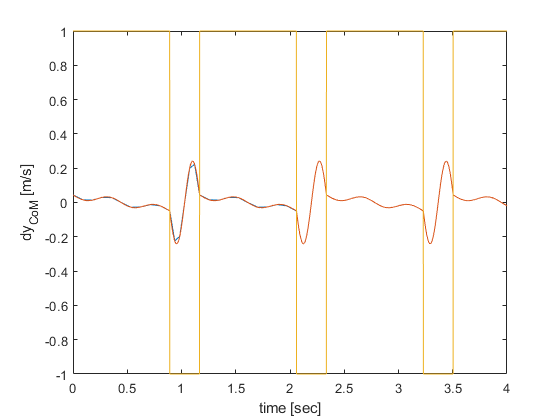


figure
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'] ...
    ,[dy_dcCoM_ss; dc.simout_ds(:,4); dy_dcCoM_ss])
hold on
plot(time, dy_CoM_calc)
plot(time, flag(:,1))
xlim([0,4])
ylabel('dy_{CoM} [m/s]')
xlabel('time [sec]')

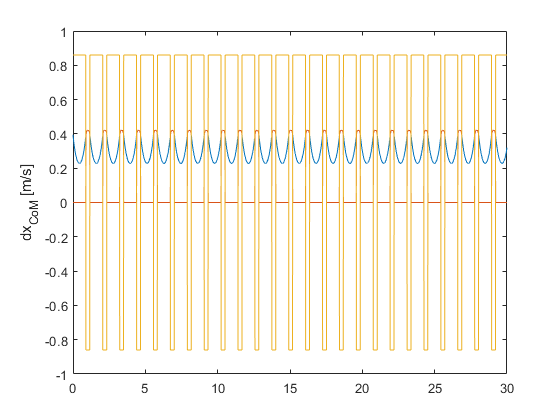


figure
plot(time, simout(:,11))
hold on
plot(time, ref_output_ds(:,2))
plot(time, 0.86*flag(:,1))
% ylim([0.76, 0.88])
ylabel('dx_{CoM} [m/s]')

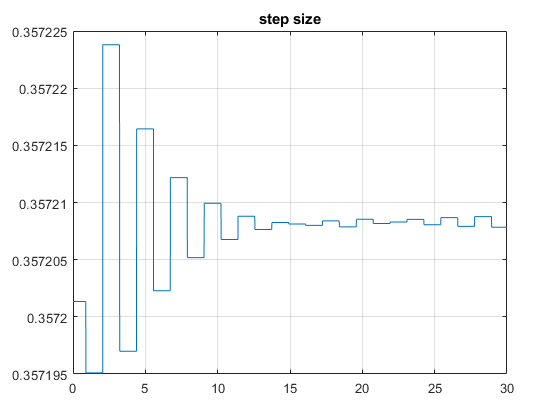


figure
plot(time, flag(:,2) - flag(:,3))
grid on
title('step size')

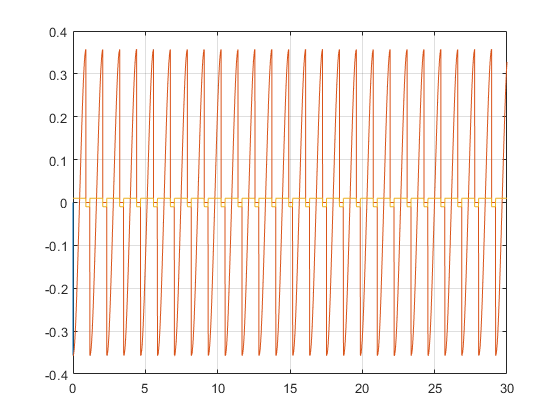

% xlim([0,4])

figure()
plot(time, ref_output_ss(:,2), 'DisplayName', 'x_{swFoot_{star}}')
hold on
plot(time, x_swFoot_calc')
plot(time, 0.01*flag(:,1))
% ylim([-0.01, 0.1])
grid on

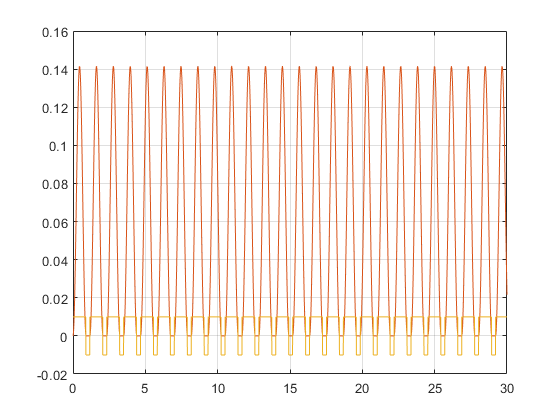


figure()
plot(time, ref_output_ss(:,3), 'DisplayName', 'y_{swFoot_{star}}')
hold on
plot(time, y_swFoot_calc')
plot(time, 0.01*flag(:,1))
% ylim([-0.01, 0.1])
grid on

% DS to SS point lift off point
lo_pt = 461;

x_CoM_LO = simout(lo_pt,5)

x_CoM_LO = 0.0064

y_CoM_LO = simout(lo_pt,6)

y_CoM_LO = 0.9852


x_M_LO = simout(lo_pt+1, 1)

x_M_LO = 0.0024

y_M_LO = simout(lo_pt+1, 2)

y_M_LO = 1.0462

theta_LO = simout(lo_pt+1, 3)

theta_LO = 4.7229

r_LO = simout(lo_pt+1, 4)

r_LO = 0.2048


x_M_err = dc.simout_ss(1,1) - x_M_LO

x_M_err = -0.1074

y_M_err = dc.simout_ss(1,2) - y_M_LO

y_M_err = -0.0055

theta_err = dc.simout_ss(1,3) - theta_LO - 2*pi

theta_err = -6.5314

r_err = dc.simout_ss(1,4) - r_LO

r_err = 0.1660


x_swLeg_LO = x_M_LO + L_thigh*cos(theta_LO)/2;
x_swFoot_LO = x_M_LO + (L_thigh + r_LO).*cos(theta_LO);

y_swLeg_LO = y_M_LO + L_thigh*sin(theta_LO)/2;
y_swFoot_LO = y_M_LO + (L_thigh + r_LO).*sin(theta_LO);

calc_x_CoM_LO = (x_M_LO*m_M + x_swLeg_LO*m_swLeg + x_swFoot_LO*m_swFoot)/(m_M + m_swLeg + m_swFoot)

calc_x_CoM_LO = 0.0030

calc_y_CoM_LO = (y_M_LO*m_M + y_swLeg_LO*m_swLeg + y_swFoot_LO*m_swFoot)/(m_M + m_swLeg + m_swFoot)

calc_y_CoM_LO = 0.9816


dx_M_LO = simout(lo_pt + 1, 7)

dx_M_LO = 0.1464

dy_M_LO = simout(lo_pt + 1, 8)

dy_M_LO = -0.0062

dtheta_LO = simout(lo_pt + 1, 9)

dtheta_LO = 1.1282

dr_LO = simout(lo_pt + 1, 10)

dr_LO = 0.0300


dx_M_err = dc.simout_ss(1,5) - dx_M_LO

dx_M_err = 0.2749

dy_M_err = dc.simout_ss(1,6) - dy_M_LO

dy_M_err = 0.0492

dtheta_err = dc.simout_ss(1,7) - dtheta_LO

dtheta_err = -1.5011

dr_err = dc.simout_ss(1,8) - dr_LO

dr_err = 0.1111


dx_swLeg_LO = dx_M_LO - L_thigh*sin(theta_LO)*dtheta_LO/2;
dx_swFoot_LO = dx_M_LO + (dr_LO).*cos(theta_LO) - (L_thigh + r_LO)*sin(theta_LO)*dtheta_LO;

dy_swLeg_LO = dy_M_LO + L_thigh*cos(theta_LO)*dtheta_LO/2;
dy_swFoot_LO = dy_M_LO + (dr_LO).*sin(theta_LO) + (L_thigh + r_LO)*cos(theta_LO)*dtheta_LO;

calc_dx_CoM_LO = (dx_M_LO*m_M + dx_swLeg_LO*m_swLeg + dx_swFoot_LO*m_swFoot)/(m_M + m_swLeg + m_swFoot)

calc_dx_CoM_LO = 0.2193

calc_dy_CoM_LO = (dy_M_LO*m_M + dy_swLeg_LO*m_swLeg + dy_swFoot_LO*m_swFoot)/(m_M + m_swLeg + m_swFoot)

calc_dy_CoM_LO = -0.0066

% checking dx_swFoot and dy_swFoot
dx_M_LO + dr_LO*cos(theta_LO) - (L_thigh + r_LO)*sin(theta_LO)*dtheta_LO

ans = 1.1674

dy_M_LO + dr_LO*sin(theta_LO) + (L_thigh + r_LO)*cos(theta_LO)*dtheta_LO

ans = -0.0255

## spring stifnness can't be less than zero

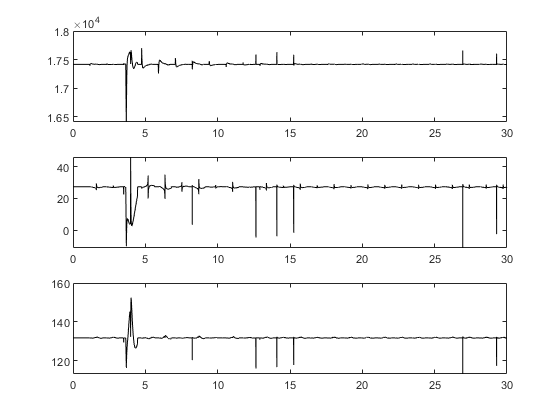

figure()
% plot(time, input_varStiff(:,1:3) + [dc.col_param.k0_ss, dc.col_param.k_swLeg, dc.col_param.k_swFoot])

subplot(3,1,1)
plot(time, inputs(:,1) + dc.col_param.k0_ss, 'k')

subplot(3,1,2)
plot(time, inputs(:,2) + dc.col_param.k_swLeg, 'k')


subplot(3,1,3)
plot(time, inputs(:,3) + dc.col_param.k_swFoot, 'k')

figure()
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'], ...
    [dc.simout_ss(:,1); zeros(11,1); 0.25 + dc.simout_ss(:,1)])

Error using plot
Vectors must be the same length.

hold on
plot(time, simout(:,1))
plot(time, flag(:,1))
xlim([0,1.2])
ylabel('x_M [m]')

figure()
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'], ...
    [dc.simout_ss(:,2); zeros(11,1); dc.simout_ss(:,2)])
hold on
plot(time, simout(:,2))
plot(time, flag(:,1))
plot(time, ref_output_ss(:,1))
xlim([0,1.2])
ylabel('y_M [m]')

figure()
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'], ...
    [dc.simout_ss(:,3); zeros(11,1); dc.simout_ss(:,3)])
hold on
plot(time, simout(:,3))
plot(time, flag(:,1))
plot(time, ref_output_ss(:,2))
xlim([0,1.2])
ylabel('theta [rad]')

figure()
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'], ...
    [dc.simout_ss(:,4); zeros(11,1); dc.simout_ss(:,4)])
hold on
plot(time, simout(:,4))
plot(time, flag(:,1))
plot(time, ref_output_ss(:,3))
xlim([0,1.2])
ylabel('r [m]')

figure()
plot([dc.time_ss'; dc.time_ss(end) + dc.time_ds'; dc.time_ss(end) + dc.time_ds(end) + dc.time_ss'], ...
    [dc.simout_ss(:,6); zeros(11,1); dc.simout_ss(:,6)])
hold on
plot(time, simout(:,8))
plot(time, flag(:,1))
% plot(time, ref_output(:,1))
xlim([0,1.2])
ylabel('dy_M [m/s]')



